# Ajuste por mínimos cuadrados

% Datos de ejemplo
x = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
y = [2.3, 2.8, 3.6, 4.5, 5.1, 5.7, 6.2, 7.1, 7.8, 8.5];

% Ajuste lineal con ajusteLineal
[a1, b1, r2_1] = ajusteLineal(x, y);
fprintf('** Función ajusteLineal:\n');

** Función ajusteLineal:


fprintf('Pendiente (a): %f\n', a1);

Pendiente (a): 0.690909


fprintf('Intersección (b): %f\n', b1);

Intersección (b): 1.560000


fprintf('Coeficiente de determinación (R^2): %f\n', r2_1);

Coeficiente de determinación (R^2): 0.997412



% Ajuste sobredeterminado con Ecuaciones Normales
[a2, b2, r2_2] = ajusteSobredeterminado(x, y, 'Normales');
fprintf('** Función ajusteSobredeterminado con Ecuaciones Normales:\n');

** Función ajusteSobredeterminado con Ecuaciones Normales:


fprintf('Pendiente (a): %f\n', a2);

Pendiente (a): 0.690909


fprintf('Intersección (b): %f\n', b2);

Intersección (b): 1.560000


fprintf('Coeficiente de determinación (R^2): %f\n', r2_2);

Coeficiente de determinación (R^2): 0.997412



% Ajuste sobredeterminado con QR
[a3, b3, r2_3] = ajusteSobredeterminado(x, y, 'QR');
fprintf('** Función ajusteSobredeterminado con QR:\n');

** Función ajusteSobredeterminado con QR:


fprintf('Pendiente (a): %f\n', a3);

Pendiente (a): 0.690909


fprintf('Intersección (b): %f\n', b3);

Intersección (b): 1.560000


fprintf('Coeficiente de determinación (R^2): %f\n', r2_3);

Coeficiente de determinación (R^2): 0.997412



% Ajuste con polyfit
p = polyfit(x, y, 1);
a4 = p(1);
b4 = p(2);
y_fit_polyfit = polyval(p, x);
y_mean = mean(y);
ss_tot = sum((y - y_mean) .^ 2);
ss_res = sum((y - y_fit_polyfit) .^ 2);
r2_4 = 1 - (ss_res / ss_tot);
fprintf('** Función polyfit:\n');

** Función polyfit:


fprintf('Pendiente (a): %f\n', a4);

Pendiente (a): 0.690909


fprintf('Intersección (b): %f\n', b4);

Intersección (b): 1.560000


fprintf('Coeficiente de determinación (R^2): %f\n', r2_4);

Coeficiente de determinación (R^2): 0.997412


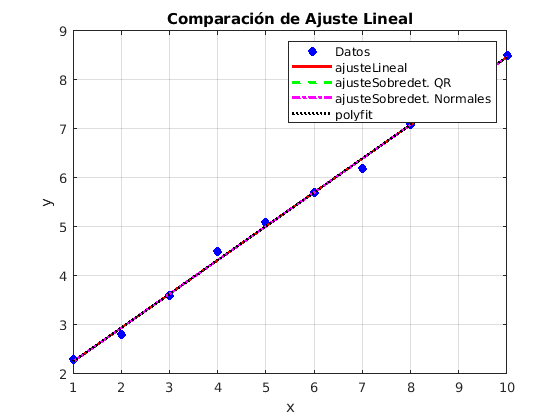


% Graficar los datos y las rectas de ajuste
figure(1);
plot(x, y, 'bo', 'MarkerFaceColor', 'b');
hold on;
plot(x, a1 * x + b1, 'r-', 'LineWidth', 2);
plot(x, a2 * x + b2, 'g--', 'LineWidth', 2);
plot(x, a3 * x + b3, 'm-.', 'LineWidth', 2);
plot(x, a4 * x + b4, 'k:', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Comparación de Ajuste Lineal');
legend('Datos', 'ajusteLineal', 'ajusteSobredet. QR', 'ajusteSobredet. Normales', 'polyfit');
grid on;
hold off;

## Linealización


$$y=g(x)=Ce^{Ax}$$


% Datos de ejemplo
x = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
y = [2.718, 7.389, 20.085, 54.598, 148.413, 403.429, 1096.633, 2980.958, 8103.084, 22026.465]; % y = 2.718 * e^{0.5x}

% Ajuste exponencial con ajusteExponencial
[C1, A1, r2_1] = ajusteExponencial(x, y);
fprintf('Función ajusteExponencial:\n');

Función ajusteExponencial:


fprintf('Coeficiente C: %f\n', C1);

Coeficiente C: 0.999948


fprintf('Coeficiente A: %f\n', A1);

Coeficiente A: 1.000007


fprintf('Coeficiente de determinación (R^2): %f\n', r2_1);

Coeficiente de determinación (R^2): 1.000000



% Ajuste exponencial con polyfit
p = polyfit(x, log(y), 1);
A2 = p(1);
C2 = exp(p(2));
y_fit_polyfit = C2 * exp(A2 * x);
y_mean = mean(y);
ss_tot = sum((y - y_mean) .^ 2);
ss_res = sum((y - y_fit_polyfit) .^ 2);
r2_2 = 1 - (ss_res / ss_tot);
fprintf('Función polyfit:\n');

Función polyfit:


fprintf('Coeficiente C: %f\n', C2);

Coeficiente C: 0.999948


fprintf('Coeficiente A: %f\n', A2);

Coeficiente A: 1.000007


fprintf('Coeficiente de determinación (R^2): %f\n', r2_2);

Coeficiente de determinación (R^2): 1.000000


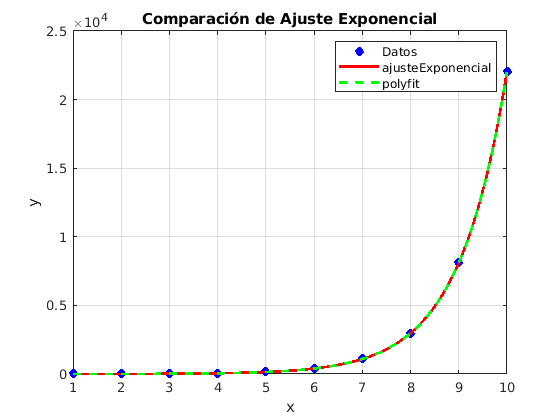


% Graficar los datos y las curvas de ajuste
figure(2);
plot(x, y, 'bo', 'MarkerFaceColor', 'b');
hold on;
x_fit = linspace(min(x), max(x), 100);
plot(x_fit, C1 * exp(A1 * x_fit), 'r-', 'LineWidth', 2);
plot(x_fit, C2 * exp(A2 * x_fit), 'g--', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Comparación de Ajuste Exponencial');
legend('Datos', 'ajusteExponencial', 'polyfit');
grid on;
hold off;

function [C, A, r2] = ajusteExponencial(x, y)
    % AJUSTEEXPONENCIAL Realiza un ajuste exponencial de la forma y = Ce^{Ax}
    %   [C, A, r2] = ajusteExponencial(x, y) devuelve los coeficientes C y A
    %   del modelo exponencial y el coeficiente de determinación r2.
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       C - Coeficiente C del modelo exponencial.
    %       A - Coeficiente A del modelo exponencial.
    %       r2 - Coeficiente de determinación (R^2).

    % Transformar los datos
    ln_y = log(y);

    % Ajustar el modelo lineal ln(y) = Ax + ln(C)
    [A, ln_C, r2] = ajusteLineal(x, ln_y);

    % Transformar ln(C) de vuelta a C
    C = exp(ln_C);
end

function [a, b, r2] = ajusteLineal(x, y)
    % AJUSTELINEAL Realiza un ajuste lineal de la forma y = ax + b
    %   [a, b, r2] = ajusteLineal(x, y) devuelve los coeficientes a y b de la
    %   recta de mejor ajuste y el coeficiente de determinación r2.
    % 
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       a - Pendiente de la recta.
    %       b - Intersección con el eje y.
    %       r2 - Coeficiente de determinación (R^2).
    
    % Calcular los coeficientes de la recta de ajuste
    n = length(x);
    Sx = sum(x);
    Sy = sum(y);
    Sxy = sum(x .* y);
    Sxx = sum(x .^ 2);
    a = (n * Sxy - Sx * Sy) / (n * Sxx - Sx .^ 2);
    b = mean(y) - a * mean(x);
    
    % Calcular el coeficiente de determinación (R^2)
    y_fit = a * x + b;
    S_r = sum((y - y_fit) .^ 2);
    y_mean = mean(y);
    S_T = sum((y - y_mean) .^ 2);
    r2 = 1 - (S_r / S_T);
end

function [a, b, r2] = ajusteSobredeterminado(x, y, metodo)
    % AJUSTESOBREDETERMINADO Realiza un ajuste lineal utilizando un sistema sobredeterminado.
    %   [a, b, r2] = ajusteSobredeterminado(x, y, metodo) devuelve los coeficientes a y b
    %   de la recta de mejor ajuste y el coeficiente de determinación r2.
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %       metodo - 'QR' para usar la descomposición QR, 'Normales' para usar las ecuaciones normales.
    %
    %   Salida:
    %       a - Pendiente de la recta.
    %       b - Intersección con el eje y.
    %       r2 - Coeficiente de determinación (R^2).

    n = length(x);
    X = [x(:), ones(n, 1)]; % Matriz de diseño
    y = y(:); % Vector columna

    if strcmp(metodo, 'QR')
        % Descomposición QR
        [Q, R] = qr(X, 0);
        coef = R \ (Q' * y);
    elseif strcmp(metodo, 'Normales')
        % Ecuaciones Normales
        coef = (X' * X) \ (X' * y);
    else
        error('Método no reconocido. Use "QR" o "Normales".');
    end

    a = coef(1);
    b = coef(2);

    % Calcular el coeficiente de determinación (R^2)
    y_mean = mean(y);
    y_fit = X * coef;
    ss_tot = sum((y - y_mean) .^ 2);
    ss_res = sum((y - y_fit) .^ 2);
    r2 = 1 - (ss_res / ss_tot);
end